- refflectivity of internal layers

- how do you express them? absolute layer refelctiivities?

- if I know bedrock reflectivity i could find absolute relefctivity of interal layers 

**** NEW 100km ECHO: AntarticaBaslerMKB\20231228_01_029 ****

**** NEWE POLE ECHO: AntarticaBaslerMKB\20230127\_01_029 ****

**^ one end goes right over the pole! (figure out which one ;-;)**

refelctivity of bedrock echo at the south pole 

- reflecttivy of nearby lake should be super high 

good to do: take a track (plane path) that goes right over pole (+-10km)

- what is observed reflectivity of bedrock and surface echo?

- take lat + long of echogram/frame & calculate dist from starting point

- start point is the south pole

- sample points along track (in front and behind)

- plot of surface reflectitiy and bedrock reflectivity

- (time of sample - 0 time (time plane crossed pole)) *pole is x = 0

- use surface echo for indices !

- if water is below bottom of ice, bottom curve will be relatively flat

- if pole below rock, bottom will vary 

- find what range indicies correspond to bed 

- plot range index of surface and bed (delta of surface - bed)

- issues if bed is highly sloped

- try to pick a good flat bed track, range index is constant 

Q: how to find reflectivity? Where to look

- 10*log10bringthess = releflectivity  

ragne line -> graph as time (as plane moves)

- elijah's doing something similar, might be helpful?

- not looking into wither or not the bed echo is flat, he's normalizing bed to some ocean data

*** what is the absolute refelctvity of internal layers ?

addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\

load Data_img_01_20240105_02_005.mat
load Data_20240105_02_005.mat



outputBrightness = 1.0e-10 *

    0.0003    0.0003    0.0003    0.0002    0.0002    0.0003    0.0003    0.0004    0.0008    0.0005    0.0007    0.0006    0.0003    0.0002    0.0002    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0003    0.0001    0.0000    0.0000    0.0001


power = calibrateBrightness(20240105, 02, 005);

depth = 1.0e+03 *

    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3421    0.3424    0.3429    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430    0.3430
    2.6344    2.6347    2.6333    2.6301    2.6275    2.6270    2.6274    2.6282    2.6286    2.6287    2.6293    2.6303    2.6319    2.6336    2.6347    2.6353    2.6355    2.6347    2.6330    2.6301    2.6265    2.6247    2.6237    2.6221    2.6200    2.6174    2.6147    2.6119    2.6095    2.6076    2.6063    2.6053    2.6056    2.6067    2.6098    2.6138    2.6191    2.6226    2.6225    2.6216    2.6207    2.6197    2.6188    2.6159    2.6124    2.6102    2.6087    2.6084

depth = twtt2Depth(twtt, 1.77); % rwo 1 = surface, row 2 = bottom variables

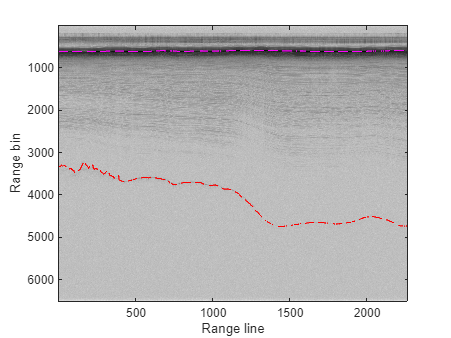

close all

echo = load('Data_img_01_20240105_02_005.mat','Data','Time','GPS_time');
h_fig = figure;
h_axes = axes;
imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);


layer = load('C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layerData\20240105_02\Data_20240105_02_005.mat','GPS_time','layerData');
Surface = interp1(echo.Time,1:length(echo.Time),layer.layerData{1}.value{2}.data);
Bottom = interp1(echo.Time,1:length(echo.Time),layer.layerData{2}.value{2}.data);
Surface = interp1(layer.GPS_time,Surface,echo.GPS_time);
Bottom = interp1(layer.GPS_time,Bottom,echo.GPS_time);

hold(h_axes,'on');
plot(Surface,'m--','parent',h_axes);
plot(Bottom,'r--','parent',h_axes);

hold off

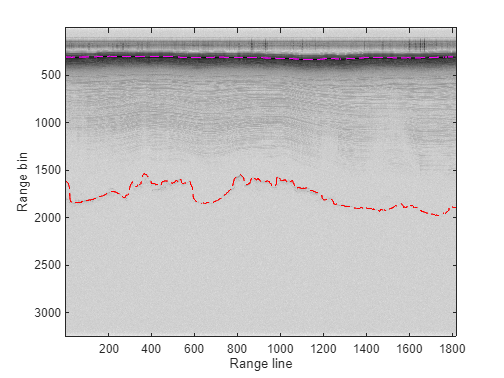

clear all

addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20231228_01\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20231228_01\

load Data_img_01_20231228_01_029.mat
load Data_20231228_01_029.mat

% load echogram! ( roughly 100 km from pole )
echo = load('Data_img_01_20231228_01_029.mat','Data','Time','GPS_time');
h_fig = figure;
h_axes = axes;
imagesc(lp(echo.Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);
hold on

layer = load('C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layerData\20231228_01\Data_20231228_01_029.mat','GPS_time','layerData');
Surface = interp1(echo.Time,1:length(echo.Time),layer.layerData{1}.value{2}.data);
Bottom = interp1(echo.Time,1:length(echo.Time),layer.layerData{2}.value{2}.data);
Surface = interp1(layer.GPS_time,Surface,echo.GPS_time);
Bottom = interp1(layer.GPS_time,Bottom,echo.GPS_time);

% plot surface/bottom lines
hold(h_axes,'on');
plot(Surface,'m--','parent',h_axes);
plot(Bottom,'r--','parent',h_axes);

hold off

% power = calibrateBrightness(20240105, 02, 005);
% depth = twtt2Depth(twtt, 1.77); % rwo 1 = surface, row 2 = bottom variables